# Testing different models individually and comparing

## Setting up the signal

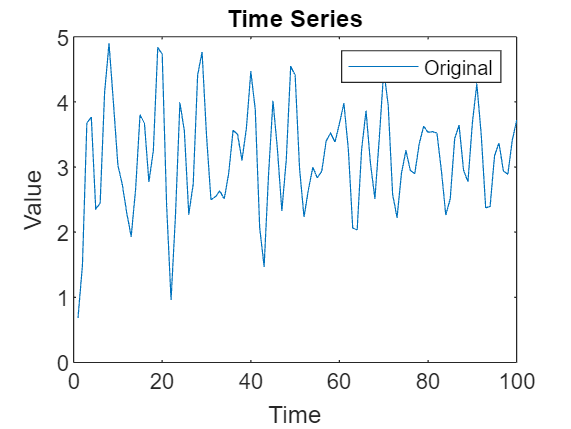

clear all;

addpath('./tensorlab/');

N = 100;
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Signal multiplicator
smul = 40*rand();

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * smul * 0.1 * t);
base_signal2 = sin(2 * pi * smul * 0.05 * t);
base_signal3 = sin(2 * pi * smul * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

time_series = signal1+signal2+signal3;

% Plot the time series
figure;
plot(time_series);
legend({"Original"})
title('Time Series');
xlabel('Time');
ylabel('Value');

## AR vs CPD mean sum

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_ms(training_series,num_predict,optimal_order,components);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.275117624561342


rmse(predictions_other,ground_truths,2)

ans =    0.303723344270660


## AR vs CPD mean full


num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_mf(training_series,num_predict,optimal_order,components);

end
disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)

## AR vs CPD columns

num_experiments = 1;
components = 3;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_col(training_series,num_predict,10,components);

end

iter 1


    "Dimension of hankel: 12"    "Dimension of hankel: 12"    "Dimension of hankel: 77"



disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.247662004366879


rmse(predictions_other,ground_truths,2)

ans =    0.566975546899120


## AR vs SVD

num_experiments = 100;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,10,components);

end

iter 1
iter 2
iter 3
iter 4
iter 5
iter 6
iter 7
iter 8
iter 9
iter 10
iter 11
iter 12
iter 13
iter 14
iter 15
iter 16
iter 17
iter 18
iter 19
iter 20
iter 21
iter 22
iter 23
iter 24
iter 25
iter 26
iter 27
iter 28
iter 29
iter 30
iter 31
iter 32
iter 33
iter 34
iter 35
iter 36
iter 37
iter 38
iter 39
iter 40
iter 41
iter 42
iter 43
iter 44
iter 45
iter 46
iter 47
iter 48
iter 49
iter 50
iter 51
iter 52
iter 53
iter 54
iter 55
iter 56
iter 57
iter 58
iter 59
iter 60
iter 61
iter 62
iter 63
iter 64
iter 65
iter 66
iter 67
iter 68
iter 69
iter 70
iter 71
iter 72
iter 73
iter 74
iter 75
iter 76
iter 77
iter 78
iter 79
iter 80
iter 81
iter 82
iter 83
iter 84
iter 85
iter 86
iter 87
iter 88
iter 89
iter 90
iter 91
iter 92
iter 93
iter 94
iter 95
iter 96
iter 97
iter 98
iter 99
iter 100


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.341691634196354


rmse(predictions_other,ground_truths,2)

ans =    0.283750669035680
